% big interval: [1, 100,000], n = 4
% middle interval: [1, 1,000], n = 30
% small interval: [1, 10], n = 6
% This is the data for the first guess of n=29 participants who played the
% mid-sized interval ([0, 1000]) version of the "Guess the Number" game
data = [590, 500, 500, 0, 500, 69, 500, 22, 500, 56, 500, 500, 13, 500, 4, ...
    500, 500, 877, 700, 45, 500, 455, 239, 921, 1, 500, 500, 529, 764]';
n = length(data)

n = 29


disp(["mean of first guess", num2str(mean(data))])

    "mean of first guess"    "406.3793"



disp(["standard deviation of first guess", num2str(std(data))])

    "standard deviation of first guess"    "270.8825"



% Perform Kolomogorov-Lilliefors to test if the data Gaussian distributed
[h,p] = lillietest(data);

if h == 1
    disp("The data is not Gaussian")
else
    disp("The data is Gaussian")
end

The data is not Gaussian


h = histogram(data);
hold on
binEdges = h.BinEdges

binEdges =            0         300         600         900        1200


binCenters = binEdges(1:end-1) + diff(binEdges)/2

binCenters =          150         450         750        1050


obsCounts = h.BinCounts % frequency 

obsCounts =      9    16     3     1


% Create a vector containing the observed counts for each bin and compute the total number of observations.
norm_data = data/1000; % normalize the data to [0, 1] support of Beta 
pd = fitdist(data,'Normal') % get the parameters from fitting a Beta distribution to (normalized) data

pd =   NormalDistribution

  Normal distribution
       mu = 406.379   [303.341, 509.417]
    sigma = 270.882   [214.967, 366.355]


expCounts = round(n * diff(cdf(pd, binEdges)))

expCounts =      8    12     6     1


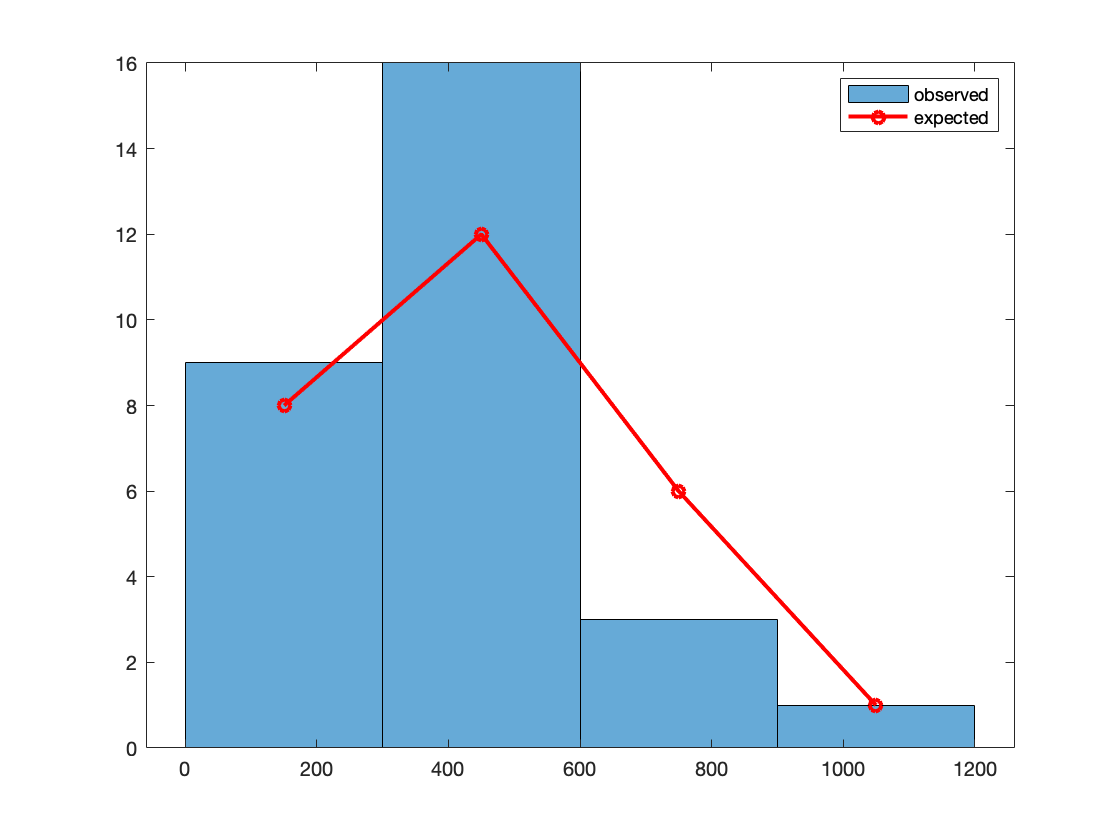

plot(binCenters, expCounts,'LineWidth',2, 'Color', 'r', "Marker", "o")
legend("observed", "expected")